# **FORÅR 2018 REEKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En kontinuert stokastisk variabel X har følgende cdf.**

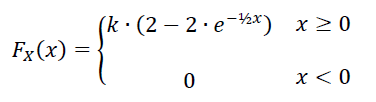

## **1.1 GYLDIG FORDELINGSFUNKTION**

For at bestemme for hvilken værdi af $k$ at $F_X \left(x\right)$ er en gyldig tæthedsfunktion anvendes, at


$$\lim_{x\to \infty } F_X \left(x\right)=1$$



$$\lim_{x\to \infty } k\cdot \left(2-2\cdot e^{-\frac{1}{2}x} \right)=1$$


syms Fx(x) k

Fx(x) = piecewise(x >= 0, (k*(2-2*exp((-1/2)*x))), 0);
k = solve(limit(Fx(x), x, inf) == 1, k)

$$k = \frac{1}{2}$$

$F_X \left(x\right)$er en gyldig fordelingsfunktion for værdien af $k=\frac{1}{2}$. 

## **1.2 TÆTHEDSFUNKTION**

For at bestemme tæthedsfunktionen $f_X \left(x\right)$ anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


diff(Fx(x))

$$ans = \left\{ \begin{array}{cl} k\,{\mathrm{e}}^{-\frac{x}{2}} & \text{ if }0<x\\ 0 & \mathrm{otherwise} \end{array}\right.$$

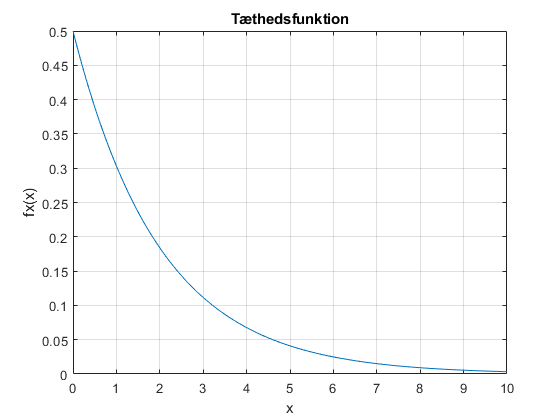

syms fx(x)

fx(x) = piecewise(x>=0, k*exp(-(x/2)), 0);

x = 0:0.01:10;

figure(1)
plot(x, fx(x));
title('Tæthedsfunktion')
xlabel('x')
ylabel('fx(x)')
grid on

Den stokastiske variabels tæthedsfunktion er bestemt til at være den ovenstående som også er skitseret.

## **1.3 SANDSYNLIGHED**

For at bestemme sandsynligheden for at den stokastiske variabel $X$har en værdi mellem 1 og 2 $P\left(1\le X\le 2\right)$anvendes, at


$$P\left(a\le X\le b\right)=\int_a^b f_X \left(x\right)\mathrm{dx}=F_X \left(b\right)-F_X \left(a\right)$$


syms fx(x)
fx(x) = piecewise(x>=0, k*exp(-(x/2)), 0);

a = 1;
b = 2;

Probability = double(int(fx(x), a, b))

Probability = 0.2387

Sandsynligheden for at den stokastiske variabel $X$ har en værdi mellem 1 og 2 er bestemt til at være 0.2387 altså 23.87%.

## 1.4 MIDDELVÆRDI

For at bestemme middelværdien også kaldt forventningsværdien anvend, at


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


syms fx(x)
f(x) = piecewise(x>=0, x*(k*exp(-(x/2))), 0);

EstimationValue = int(f(x), -inf, inf)

$$EstimationValue = 2$$

# **2 STOKASTISKE PROCESSER**

**En stokastisk proces er givet ved**

## **2.1 REALISERING**

Realiseringen er lavet i matlab med følgende kode.

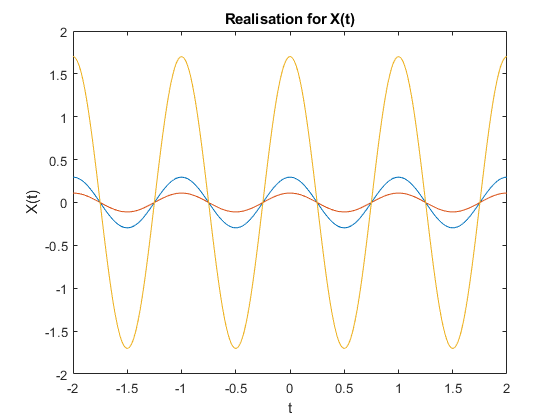

[a, b] = deal(0, 2);

A = a + (b-a) * rand(3, 1);

t = -2:0.01:2;

B = cos(2*pi*t);

X = A .* B;

figure(2)
plot(t, X)
title('Realisation for X(t)')
xlabel('t')
ylabel('X(t)')

Tre realiseringer er vist i ovenstående figure. 

## **2.2 TEMPORALE MIDDELVÆRDI OG VARIANS**

Den temporale middelværdi kan bestemmes som følgende


$$\hat{\mu_{X_i } } ={\left\langle X_i \right\rangle }_T =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x_i \left(t\right)\mathrm{dt}$$


Da arealet over og under en cosinus er lig med nul og vides altså at middelværdien er lig med nul. Set ud fra ovenstående udtryk ses at integralet af cosinus funktionen giver arelaet hvilket dermed er lig med nul.

syms T t

Eq = (1/T) * int(A(1, :)*cos(2*pi*t), -(T/2), (T/2));

TemporalMean = double(limit(Eq, T, inf))

TemporalMean = 0

Ovenstående viser den bestemte temporale mean for en realisering.

syms T t

Eq = (1/T) * int(((A(1, :)*cos(2*pi*t))^2) - 0^2 , -(T/2), (T/2));

TemperalAverage = double(limit(Eq, T, inf))

TemperalAverage = 0.0436

Ovenstående viser den bestemte variance for en realisering.

## **2.3 ENSEMBLE MIDDELVÆRDI OG VARIANS**

For at bestemme middelværdien anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack A\cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)\right\rbrack =E\left\lbrack A\right\rbrack +\mathrm{cos}\left(2\cdot \pi \cdot t\right)$$


Da $A$ er uniform fordelt anvendes, at


$$E\left\lbrack A\right\rbrack =\frac{a+b}{2}$$


EnsembleMean = (a + b) / 2 * cos(2*pi*t)

$$EnsembleMean = \cos\left(2\,\pi \,t\right)$$

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left\lbrack X\left(t\right)\right\rbrack =\mathrm{Var}\left\lbrack A\cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)\right\rbrack$$


Hertil anvendes reglen om linearitet hvormed


$$\mathrm{Var}\left\lbrack \mathrm{aX}+b\right\rbrack =a^2 \cdot \mathrm{Var}\left\lbrack X\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\left(t\right)\right\rbrack =\mathrm{Var}\left\lbrack A\right\rbrack \cdot \mathrm{cos}\left(2\cdot \pi \cdot t\right)$$


Da $A$er uniform fordelt anvendes, at


$$\sigma^2 =\frac{{\left(b-a+1\right)}^2 -1}{12}$$


EnsembleVariance = ((1/12) * (b-a)^2) * (cos(2*pi*t)^2)

$$EnsembleVariance = \frac{{\cos\left(2\,\pi \,t\right)}^{2}}{3}$$

Variansen er dermed bestemt til at være ovenstående.

## 2.4 PROCESSEN

Processen er ikke WSS da middelværdi og variance for ensemble af afhængig af tiden. Da processen ikke er WSS kan processen heller ikke være ergodisk, hvilket den heller ikke er.

# **3 SANDSYNLIGHED**

En producent af spændingsforsyninger tester de færdige apparater inden de forlader fabrikken. Til testen er udviklet en automatisk test. Testen er imidlertid ikke helt fejlfri. Hvis et apparat testes positiv (godkendes), vil det kun i 90% af tilfældene faktisk overholde specifikationerne. Og hvis et apparat testes negativ (ikke godkendes), vil det kun være i 80% af tilfældene, at det ikke overholder specifikationerne. Samlet set godkendes 85% af alle apparaterne ved testen.

A : POSITIV TEST

B : OVERHOLDER SPECIFIKATIONER


$$P\left(B|A\right)=0\ldotp 9,\;\;P\left(\overline{B} |\overline{A} \right)=0\ldotp 8$$



$$P\left(A\right)=0\ldotp 85$$


BGivenA = 0.9;
NotBGivenNotA = 0.8;
A = 0.85;

## **3.1 BETINGET SANDSYNLIGHED**

For at bestemme sandsynligheden for at et apparat overholder spec selvom det er teset negativt anvendes, at


$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


BGivenNotA = 1 - NotBGivenNotA

BGivenNotA = 0.2000

Sandsynligheden er dermed bestemt til at være 0.20 altså 20%.

## **3.2 FÆLLESMÆNGDE**

For at bestemme sandsynligheden for at et apparat både overholder spec og testes positiv anvendes, at


$$P\left(B\cap A\right)=P\left(B|A\right)\cdot P\left(A\right)$$


AAndB = BGivenA * A

AAndB = 0.7650

Sandsynligheden er dermed bestemt til at være 0.765 altså 76.5%. 

## **3.3 TOTALE SANDSYNLIGHED**

For at bestemme hvor mange ud af 1000 producerede apparater der forventes ikke at overholde spec findes først den totale sandsynlighed for at overholde spec som følgende.


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$


B = BGivenA * A + BGivenNotA * (1 - A)

B = 0.7950

Sandsynligheden for ikke at overholde spec findes som


$$P\left(\overline{B} \right)=1-P\left(B\right)$$


NotB = 1 - B

NotB = 0.2050

Mængden af apparater ud af de 1000 som forventes ikke overholde spec findes som


$$P\left(\overline{B} \right)=\frac{N_{\overline{B} } }{N_{\mathrm{Total}} }$$


Amount = NotB * 1000

Amount = 205.0000

 Det forventede antal apparater som ikke overholde spec er bestemt til at være 205.

# **4 STATISTIK**

Til kalibrering af en elektronisk vægt er der udført en række målinger af udgangsspændingen af transduceren ved forskellige vægtbelastninger. Målingerne er angivet i tabellen.

Der forventes en lineær sammenhæng mellem de målte spændinger og vægtbelastningen.

## **4.1 PLOT**

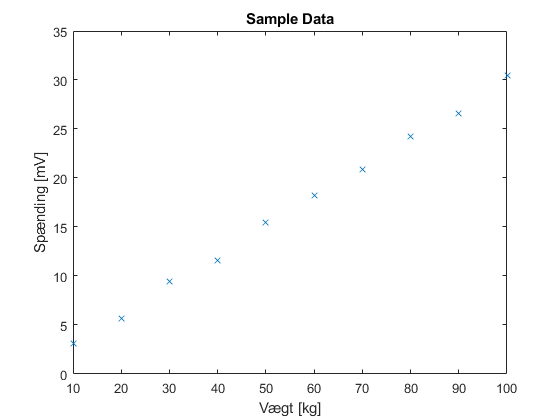

Weight = [10, 20, 30, 40, 50, 60, 70, 80, 90, 100];
Voltage = [3.11, 5.68, 9.41, 11.58, 15.42, 18.18, 20.87, 24.25, 26.58, 30.42];

figure(3)
plot(Weight, Voltage, 'x')
title('Sample Data')
xlabel('Vægt [kg]')
ylabel('Spænding [mV]')

## **4.2 LINEÆR REGRESSION**

For at anvende lineære regression anvendes lineær tilnærmelse ved, at


$$\hat{x} =\beta \cdot t+\alpha$$


Dertil anvendes, at 


$$\beta^ˆ =\frac{\sum_{i=1}^n \left(x-\overline{x} \right)\cdot \left(y-\overline{y} \right)}{\sum_{i=1}^n {\left(x-\overline{x} \right)}^2 }$$



$$\alpha^ˆ =\overline{y} -\beta^ˆ \cdot \overline{x}$$


Samt at der for middelværdien gælder, at


$$\overline{x} =\frac{1}{n}\cdot \sum_{i=1}^n x_i$$


WeightMean = mean(Weight);
VoltageMean = mean(Voltage);

beta = sum((Weight - WeightMean) .* (Voltage - VoltageMean)) / sum((Weight - WeightMean).^2);
alpha = VoltageMean - beta * WeightMean;

Fitting = beta * Weight + alpha

Fitting =     2.9976    6.0093    9.0209   12.0325   15.0442   18.0558   21.0675   24.0791   27.0907   30.1024


## **4.3 LINEÆR PLOT**

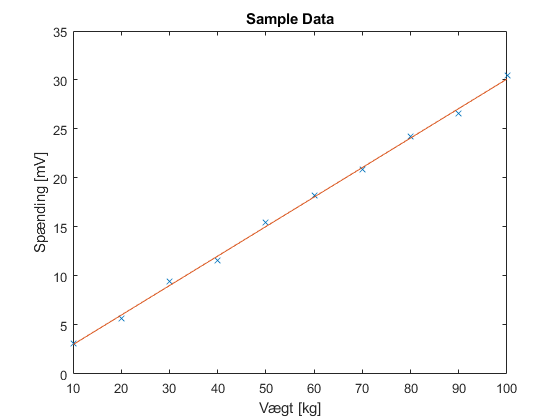

figure(4)
plot(Weight, Voltage, 'x')
hold on
plot(Weight, Fitting);
title('Sample Data')
xlabel('Vægt [kg]')
ylabel('Spænding [mV]')
hold off

## 4.4 RESIDUALER

For at tegne of beregne residualer anvendes følgende udtryk.


$$\epsilon_i =y_i -\left(\alpha +\beta \cdot x_i \right)$$


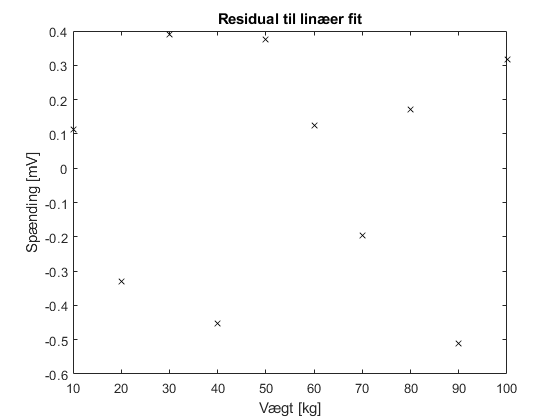

Residuals = Voltage - (alpha + beta * Weight);

figure(5)
plot(Weight, Residuals, 'kx');
title('Residual til linæer fit')
xlabel('Vægt [kg]')
ylabel('Spænding [mV]')

## 4.5 KONFIDENSINTERVAL

For at bestemme konfidensintervallet for hældningen anvendes den emperiske varians 


$$s_r^2 =\frac{1}{n-2}\cdot \sum_{i=1}^n {\left(y_i -\left(\alpha^ˆ +\hat{\beta_{x_i } } \right)\right)}^2$$


Samt udtrykket for konfidensintervallet givet ved


$$\beta_{\pm } =\beta^ˆ \pm t_0 \cdot \frac{s_r }{\sqrt{\sum_{i=1}^n {\left(x_i -\overline{x} \right)}^2 }}$$


n = length(Weight) - 2;

TZero = tinv(0.975, n);
EmpiricalVariance = (1 / (n - 2)) * sum((Voltage - (alpha + beta * Weight)).^2);

delta = TZero * (sqrt(EmpiricalVariance) / sqrt(sum((Weight-WeightMean).^2)));

Beta.min = beta - delta;
Beta.max = beta + delta;

Beta

Beta = struct with fields:
    min: 0.2905
    max: 0.3119


Konfidensintervallet for hældningen er dermed bestemt til at være $\left\lbrack 0\ldotp 2905,0\ldotp 3119\right\rbrack$.

## 4.6 LINEARITET

Residualplottet viser at residualerne er tilfældigt fordelt uafhængig af vægten. Konfidensintervallet er meget lille og begge dele betyder at antagelsen om linearitet mellem vægten samt spændingen er en god antagelse.


$$\frac{\triangle \beta }{\beta }=0\ldotp 0355$$
